# Parallel Simulation Processing, Raibert Controller

**Last modified: **August 18, 2022

**Authors: **Jack Butler

**Description: **This MATLAB live script unpacks the data from parallel simulation of the Raibert controller.

**Necessary Files:**

- `parsim_in_Raibert: `Input parameters to the most recent batch simulation of the Raibert controller

- `parsim_out_Raibert: `Output of the most recent batch simulation of the Raibert controller

### Load Simulation Results

The simulation results are usually pretty big files, so this might take some time!

clear; close all; clc;

%load the datasets
siminput = load("parsim_in_Raibert.mat").parameters;
simoutput = load("parsim_out_Raibeiyuhb nmrt.mat").parallelout;

%figure out their dimensions
indims = size(siminput);
outdims = size(simoutput);

### Initialize Variables

tout = zeros(2,2);
speed = zeros(2,2);
rgain = zeros(2,2);
jointval = zeros(2,2);
z_pos = zeros(2,2);

### Unpack Simulation Results

Sorting the simulation data into input and output arrays.

%unpacking inputs
for i = indims(1):-1:1
    for j = indims(2):-1:1
        for k = indims(3):-1:1

        jointval(i,j,k) = siminput(i,j,k,1);
        rgain(i,j,k) = siminput(i,j,k,2);
        initangle(i,j,k) = siminput(i,j,k,3);

        end
    end
end

%unpacking outputs
for i = outdims(1):-1:1
    for j = outdims(2):-1:1
        for k = outdims(3):-1:1
    
        tout(i,j,k) = max(simoutput(i,j,k).tout);
        speed(i,j,k) = mean(simoutput(i,j,k).speed);
        z_pos(i,j,k) = max(simoutput(i,j,k).hop_height);

        end
    end
end

%reshaping unpacked stuff into 1xn matrices
tout = reshape(tout,[],1);
rgain = reshape(rgain,[],1,1);
jointval = reshape(jointval,[],1);
speed = reshape(speed,[],1);
z_pos = reshape(z_pos,[],1);
speed = reshape(speed,[],1);
initangle = reshape(initangle,[],1);

### Success/Fail Detection

Sorts the array results into successes and failures.

%initializing variables
success_v_fail = zeros(length(tout),1); % contains the indices of successful runs

% success and failure detection
for i = length(tout):-1:1
    if(tout(i) == 4) % make this however long your simulation was
        success_v_fail(i) = 1;
    else
        success_v_fail(i) = 0;
    end
end

%removing the zeros from the successes array
successes = nonzeros(successes);

%making arrays of successful parameters
for i = length(successes):-1:1

    successful_jumps(i) = z_pos(successes(i));
    successful_speeds(i) = speed(successes(i));
    successful_rgains(i) = rgain(successes(i));
    successful_springconsts(i) = amplitude(successes(i));

end

### Plot the Data

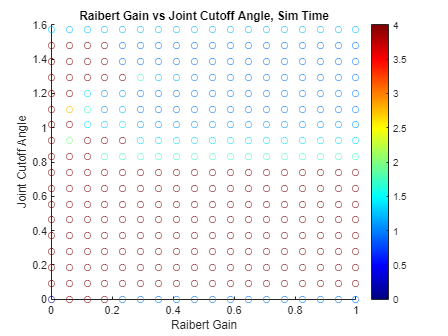

%making a scatter plot to find successful ranges easier
figure
scatter(rgain,jointval,[],tout)
colormap(jet)
colorbar
xlabel("Raibert Gain")
ylabel("Joint Cutoff Angle")
title("Raibert Gain vs Joint Cutoff Angle, Sim Time")
hold off

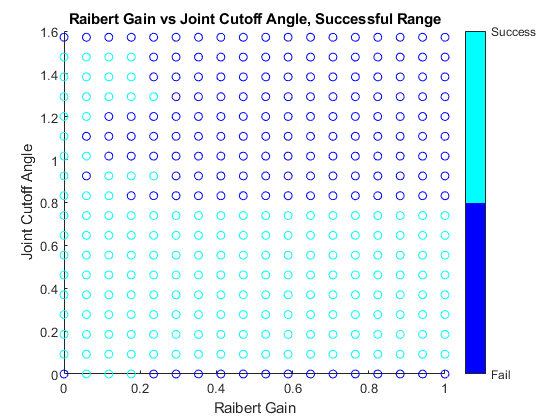


% showing relations between parameters and sim time
figure
scatter(rgain,jointval,[],success_v_fail)
colormap(jet(2))
colorbar('Ticks',[0,1],'TickLabels',{'Fail','Success'})
xlabel("Raibert Gain")
ylabel("Joint Cutoff Angle")
title("Raibert Gain vs Joint Cutoff Angle, Successful Range")
hold off 

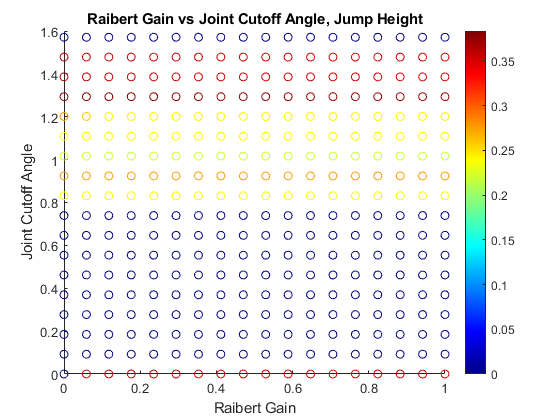


% showing relations between parameters and max jump height
figure
scatter(rgain,jointval,[],z_pos)
colormap(jet)
colorbar
xlabel("Raibert Gain")
ylabel("Joint Cutoff Angle")
title("Raibert Gain vs Joint Cutoff Angle, Jump Height")
hold off

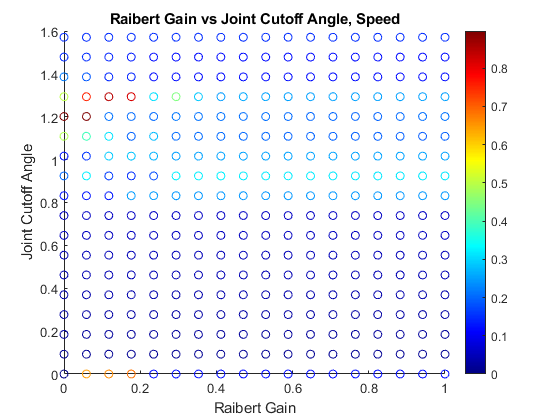


% showing relations between parameters and max speed
figure
scatter(rgain,jointval,[],speed)
colormap(jet)
colorbar
xlabel("Raibert Gain")
ylabel("Joint Cutoff Angle")
title("Raibert Gain vs Joint Cutoff Angle, Speed")
hold off